%test function for SFD and BMD 
n = 1250; % Number of locations to evaluate bridge failure
L = 1250; % Length of bridge
x = linspace(0, L, n); % Define x coordinate -> array of 0 to L increasing by number of locations to see bridge failure at 
SFD_PL = zeros(1, n); % Initialize SFD(x)
BMD_PL = zeros(1, n);
P = 185; % point load 
P_total = zeros(2, 1);
E = 4000; %currently I am choosing to pass E and I through ApplyPL but if we want to change that I can do that too

Cross Sections 

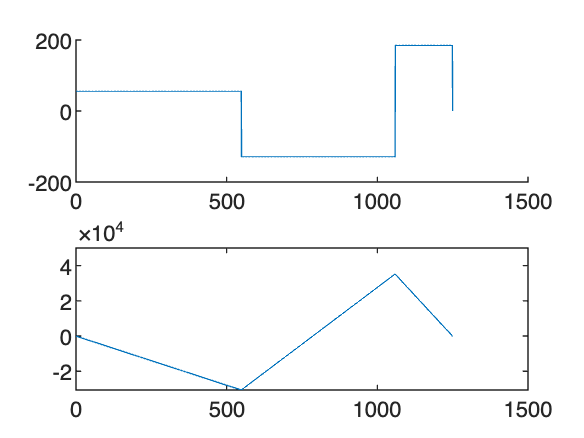

%% 2. Define cross-sections
% There are many (more elegant ways) to construct cross-section objects
xc = [0 400 1060 L]; % Location, x, of cross-section change
dia = [0 550 1060 1250];% Diaphragm Spacing -> change to locations of the dia instead
dia_tft =[1.27 1.27 1.27 1.27];
dia_bft = [100 100 100 100];
dia_hw = [75 75 75 75];
dia_bftthick = [1.27 1.27 1.27 1.27];
dia_bfb = [80 80 80 80];
bft = [100 100 100 100]; % Top Flange Width
tft = [1.27 1.27 1.27 1.27]; % Top Flange Thickness
hw = [75 75 75 75]; % Web Height
tw = [1.27 1.27 1.27 1.27]; % Web Thickness (Assuming 2 separate webs)
bfb = [80 80 80 80]; % Bottom Flange Width
tfb = [1.27 1.27 1.27 1.27]; % Bottom Flange Thickness
gtt = [10 10 10 10]; %glue tab
bfthick = [1.27 1.27 1.27 1.27];
%from what i can tell, these are assigning the different cross sections at
%each of the changes areas
%looks like diaphgram is at 0, 550, and 1250 and web height changes at 550


[SFD_PL, BMD_PL, SFD_Max, BMD_Max] = ApplyPL(550, P, x, SFD_PL, P_total);
[SFD_PL, BMD_PL, SFD_Max, BMD_Max] = ApplyPL(1250, P, x, SFD_PL, P_total);

Plotting(SFD_PL, BMD_PL, x)

[b1, b2, b3, t, y_bar, y_top, y_bot, tf, I] = sect_prop(xc, bft, tft, hw, tw, bfb, tfb, dia, L, x, gtt, bfthick, dia_bftthick, dia_hw, dia_tft, dia_bft, dia_bfb);

I_is = 	1.0e+06 *

    2.9302    0.4125    0.4125    0.4125    0.4125    0.4125    0.4125    0.4125    0.4125    0.4125    0.4125    0.4125    0.4125    0.4125    0.4125    0.4125    0.4125    0.4125    0.4125    0.4125    0.4125    0.4125    0.4125    0.4125    0.4125    0.4125    0.4125    0.4125    0.4125    0.4125    0.4125    0.4125    0.4125    0.4125    0.4125    0.4125    0.4125    0.4125    0.4125    0.4125    0.4125    0.4125    0.4125    0.4125    0.4125    0.4125    0.4125    0.4125    0.4125    0.4125


a = I (1, :)

a = 	1.0e+06 *

    2.9302    0.4125    0.4125    0.4125    0.4125    0.4125    0.4125    0.4125    0.4125    0.4125    0.4125    0.4125    0.4125    0.4125    0.4125    0.4125    0.4125    0.4125    0.4125    0.4125    0.4125    0.4125    0.4125    0.4125    0.4125    0.4125    0.4125    0.4125    0.4125    0.4125    0.4125    0.4125    0.4125    0.4125    0.4125    0.4125    0.4125    0.4125    0.4125    0.4125    0.4125    0.4125    0.4125    0.4125    0.4125    0.4125    0.4125    0.4125    0.4125    0.4125


deflections 

defls = deflections(x, BMD_PL, I, E)

delta_CA = 6.3334

delta_BA = 1.2661

defls = 1.9006

defls = 1.9006

SFD and BMD

function [SFD_PL, BMD_PL, SFD_Max, BMD_Max] = ApplyPL(L, P, x, SFD_PL, P_total) %add BMD in later 
P_total(1, end+1)= P;
P_total(2, end) = L;
total_down = sum(P_total (1, :));
moment = 0;
a = size(P_total);
a = a(1,1);
%BMD_PL = zeros(1, length(x));

%reaction forces calculation 
for i = 1: a-1
    moment = moment + P_total(1,a)*P_total(2,a); %since all the point loads point in the same direction anyway
end

%since supports are always in the same place, rxn forces can be calculated
By = moment ./ 1060;
Ay = total_down - By; 

%adding the reaction forces to SFD_PL 
%Adding Ay
for i = 1:length(x);
    SFD_PL(1, i) = SFD_PL(1, i) + Ay; 
end 

%Adding By 
for i = 1060:length(x);
    SFD_PL(1, i) = SFD_PL(1, i) + By; 
end 

%adding in the point load 
for i = L : length(x)
    SFD_PL(1, i) = SFD_PL(1, i) - P_total(1, end);
end

BMD_PL = cumsum(SFD_PL); 

%checking to see if SFD and BMD return to 0  
%check_final_value = SFD_PL(1, end)
%check_final_value2 = BMD_PL(1, end) %hmm this is the same sus thing i found in the hand calculations hmm

SFD_Abs = abs(SFD_PL);

SFD_Max = max(SFD_Abs);

BMD_Abs = abs(BMD_PL);

BMD_Max = max(BMD_Abs);
end

Plotting function

function Plotting(SFD_PL, BMD_PL, x)
subplot(2, 1, 1);
hold on 
plot(x, SFD_PL) %figure out how to shift the x-axis up 
 
%positive on bottom 
subplot(2, 1, 2);
plot(x, -(BMD_PL))
hold off
end

Cross section

function [b1, b2, b3, t, y_bar, y_top, y_bot, tf, I] = sect_prop(xc, bft, tft, hw, tw, bfb, tfb, dia, L, x, gtt, bfthick, dia_bfthick, dia_hw, dia_tft, dia_bft, dia_bfb)
b1 = zeros(1,length(x));
b2 = zeros(1,length(x));
b3 = zeros(1,length(x));
t = zeros(1,length(x));
y_bar = zeros(1,length(x));
y_top = zeros(1,length(x));
y_bot = zeros(1,length(x));
tf = zeros(1,length(x));
I = zeros(1,length(x));

for r = 1:length(hw)
    hw(1, r) = hw(1, r) - tft(1, r) - bfthick(1, r); 
    dia_hw(1, r) = dia_hw(1, r) - dia_tft(1, r) - dia_bfthick(1, r);
    %calcs the height of web minus
    %thickness of top and bottom flanges 
end
%load up the cross section property vectors with the cross section 
for i = 1:length(xc)
   a = xc(1, i);
   if i <= 2
       b = 1;
   else 
       b = xc(1, i-1);
   end 
 
   for j = b:a
       %adds the values of the cross section properties to the vectors
       a1 = (tft(1, i)).*(bft(1,i)); %top flange area
       a2 = (gtt(1, i)-tw(1, i)).*(tw(1, i)); %glue tab area
       a3 = (hw(1, i)).*(tw(1, i)); %area of the webs
       a4 = (bfb(1, i)).*(bfthick(1, i)); %area of the bottom flange
       y1= bfthick(1, i) + hw(1, i) + (1/2).*tft(1, i);
       y2= bfthick(1, i) + hw(1, i) -((1/2).*1.27);
       y3= bfthick(1, i) + (1/2).*hw(1, i);
       y4= bfthick(1, i).*1/2 ;
 
       y_bar(1, j) = ((a1.*y1)+2.*(a2.*y2)+2.*(a3.*y3)+(a4.*y4))./(a1+2.*a2+2.*a3+a4);
       %note: y_bar doesn't change even if u add diaphgram 
 
       b1(1, i)= (bft(1, i) - bfb(1, i)).*1/2;
       b2(1, i)= bfb(1, i); % assumes that the structure is symmterical
       b3(1, i) = b1(1, i);
       t(1, i) = tw(1, i);
       y_bot(1, i) = y_bar(1, j);
       y_top(1, i) = (bfthick(1, i) + hw(1, i) + tft(1, i)) - y_bot(1, i);
       tf(1, i) = tft(1, i);
 
       d1= y1 - y_bar(1, j);
       d2= y2 - y_bar(1, j);
       d3= y3 - y_bar(1, j);
       d4= y_bar(1, j) - y4;

       Io1 = ((tft(1, i)).^3).*(bft(1,i))./12;
       Io2 = (gtt(1, i)-tw(1,i)).*((tw(1, i).^3))./12;
       Io3 = ((hw(1, i).^3).*(tw(1, i))./12);
       Io4 = (bfb(1, i)).*((bfthick(1, i).^3))./12;

       I(j) = (Io1 + a1.*(d1.^2) + (2.*(Io2 + a2.*(d2.^2))) + 2.*((Io3 + a3.*(d3.^2))) + Io4 + a4.*(d4.^2)); 
   end
end 

%for the specific locations of the diaphragms
for i = 1:length(dia)
    z = dia(1, i);
    if z == 0
        z = 1;
    end 
    %don't have to recalc y_bar since symmterical addition of material 
    %don't think i have to do anything with b2, or b3 for this either and
    %ytop and y bottom stay the same since y_bar no change 
    
    t(1, i) = bfb(1, i);
    y1= dia_bfthick(1, i) + dia_hw(1, i) + (1/2).*dia_tft(1, i);
    y2= (dia_bfthick(1, i) + dia_hw(1, i)).*1/2;
    d01= y1 - y_bar(1, z);
    d02 = y2 - y_bar(1, z);
    a01 = dia_tft(1, i).*(dia_bft(1,i));
    a02 = dia_bfb(1, i).*((dia_hw(1, i)-dia_tft(1, i)));
    I01 = ((dia_tft(1, i)).^3).*(dia_bft(1,i))./12;
    I02 = (dia_bfb(1, i).*((dia_hw(1, i)+ dia_bfthick(1, i)).^3))./12; %if there's ever an error check this place 
    
    I(z) = I01 + a01.*(d01).^2 + I02 + a02.*(d02).^2 ;
end 
I_is = I(1, :)
end


Function 5-Deflections

function [defls] = deflections(x, BMD_PL, I, E )
%first find curvature diagram/array

curv = (BMD_PL)./(E.*I);

%then, using similar triangles approach, find 
%define beam as a------b-----c
%tangent at a to c and tangent at a to b(every point that you want to find
%the deflection at any point 

%for midpoint deflections:
b = 530;
delta_CA = 0;
delta_BA = 0;
LAB = b;
LAC = 1060;
res1= zeros(1, LAC);
res2= zeros(1, LAB);

%finding tangent CA
for i = 1:1060-1
   res1(1, i) = (((2.*curv(1, i+1)+curv(i)))./(3.*(curv(1, i+1)+curv(1, i)))+ LAC - x(1, i+1)).*((curv(1, i+1)+(curv(1, i))./2));
end
 
delta_CA =sum(res1)

  
 
%finding tangent to AB
for i = 1:b -1
   res2(1, i) = (((2.*curv(1, i+1)+curv(i)))./(3.*(curv(1, i+1)+curv(1, i)))+ LAB - x(1, i+1)).*((curv(1, i+1)+(curv(1, i))./2));
end
 
delta_BA =sum(res2)
 
defls = (((LAB*delta_CA)/LAC)-delta_BA)
end